## FFT demo - comparing FFT and dot product

Start by making a discrete time vector... 

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, a Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

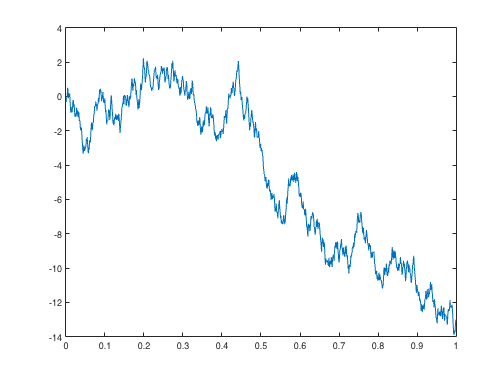

temp1 = rand(size(time))-.5; % zero-cetered white nois
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white nois
figure
plot(time, brownsig)

Now we make 3 simple signals, to be added to the brownian noise. We make them half of the length of the Brownian noise to show some of teh features of Fourier transform later

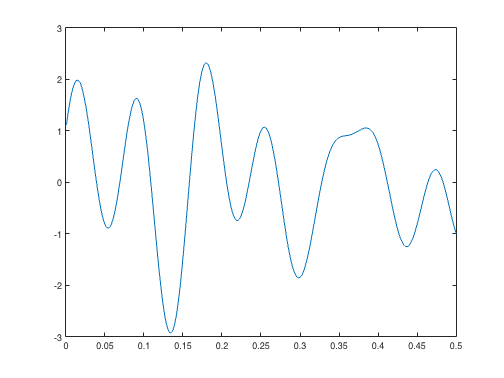

Sin6Hz = sin(2*pi*time(1:500)*6); % 6 Hz
Cos11Hz = cos(2*pi*time(1:500)*11); % 11 Hz
Sin13Hz = sin(2*pi*time(1:500)*13); % 13 Hz

sumsig = Sin6Hz + Cos11Hz + Sin13Hz; 
figure
plot(time(1:500), sumsig)

The sum of the three test signals, two sinoids, one cosinoid is now added to the Brownian noise

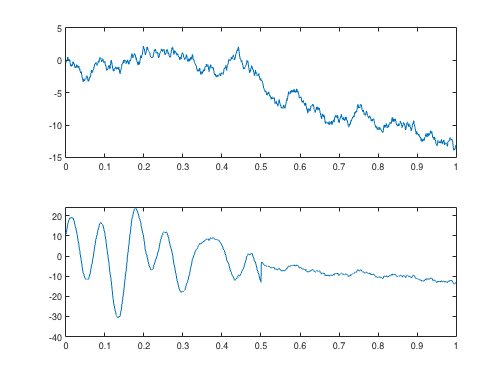

testsig  = brownsig; 
testsig(1:500) = brownsig(1:500) + sumsig.*10; %multiply sum of sine/cosine signals by 2 to make more prominent
figure
subplot(2,1,1), plot(time, brownsig)
subplot(2,1,2), plot(time, testsig)

Now, the Discrete Fourier Transform, resulting in a complex spectrum with real (cosine-base) and imaginary (sine-base) components

complexspectrum = fft(testsig);

We have a 1-sec segment, which means the frequency resolution is 1 Hz; sampled at 1000 Hz, the maximum axis goes from 0 Hz to 500 Hz. 

faxis = 0:500; 

Plot the resulting spectra, one for the real part, one for the imaginary part, and the (combined) amplitude spectrum. We plot only frequencies between 0 and 30 Hz

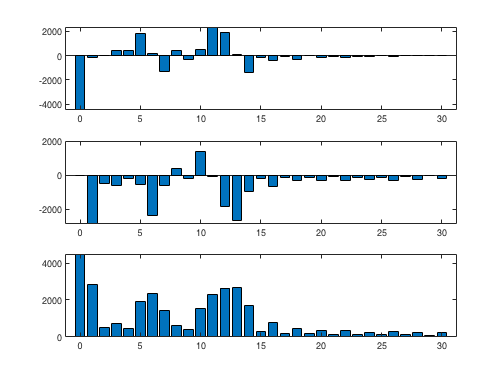

figure
subplot(3,1,1), bar(faxis(1:31), real(complexspectrum(1:31))) % the real part
subplot(3,1,2), bar(faxis(1:31), imag(complexspectrum(1:31))) % the imaginary part
subplot(3,1,3), bar(faxis(1:31), abs(complexspectrum(1:31))) % the absolute value

and now, we do the dot product of integer sines and cosines and the test signals. 

for x = 1:30; sindot1(x) = testsig_sines*sin(time*2*pi*x)'; end
for x = 1:30; sindot2(x) = testsig_sincos*sin(time*2*pi*x)'; end
for x = 1:30; cosdot1(x) = testsig_sines*cos(time*2*pi*x)'; end
for x = 1:30; cosdot2(x) = testsig_sincos*cos(time*2*pi*x)'; end

Plot the resulting spectra

figure
plot(1:30, abs(fft1(2:31)), 'r')
hold on
plot(1:30, sindot1(1:30), 'b')
title('Signal with only sines')
legend('Fourier amplitude', 'Sine-based dot Product')

figure
plot(1:30, abs(fft2(2:31)), 'r')
hold on
plot(1:30, sindot2(1:30), 'b')
title('Signal with sines and cosine')
legend('Fourier', 'Sine-based dot Product')

figure
plot(0:30, angle(fft1(1:31)))
hold on
plot(0:30, angle(fft2(1:31)))